# SNW_DS_PARAM Base Solution Analysis

This is the example vignette for function: [**snw_ds_main**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/params/snw_ds_main.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function solves for vfi and gets distribution induced by policy functions and exogenous distributions. Base Simulations.

## Test SNW_DS_MAIN Defaults Base

Call the function with testing defaults. Note:

- mean of a_ss = mp_dsvfi_results('A_agg')/sum(Phi_true,'all')

- mean of c_ss = (mp_dsvfi_results('Y_inc_agg') - mp_dsvfi_results('Tax_revenues'))/sum(Phi_true,'all')

mp_params = snw_mp_param('default_base');
mp_controls = snw_mp_control('default_test');
mp_controls('bl_print_vfi') = true;
mp_controls('bl_print_ds') = true;
mp_controls('bl_print_vfi_verbose') = false;
mp_controls('bl_print_ds_verbose') = false;
mp_controls('bl_vfi_store_all') = true;
mp_controls('bl_ds_store_all') = true;
[mp_dsvfi_results] = snw_ds_main(mp_params, mp_controls);

SNW_VFI_MAIN: Finished Age Group:18 of 18
SNW_VFI_MAIN: Finished Age Group:17 of 18
SNW_VFI_MAIN: Finished Age Group:16 of 18
SNW_VFI_MAIN: Finished Age Group:15 of 18
SNW_VFI_MAIN: Finished Age Group:14 of 18
SNW_VFI_MAIN: Finished Age Group:13 of 18
SNW_VFI_MAIN: Finished Age Group:12 of 18
SNW_VFI_MAIN: Finished Age Group:11 of 18
SNW_VFI_MAIN: Finished Age Group:10 of 18
SNW_VFI_MAIN: Finished Age Group:9 of 18
SNW_VFI_MAIN: Finished Age Group:8 of 18
SNW_VFI_MAIN: Finished Age Group:7 of 18
SNW_VFI_MAIN: Finished Age Group:6 of 18
SNW_VFI_MAIN: Finished Age Group:5 of 18
SNW_VFI_MAIN: Finished Age Group:4 of 18
SNW_VFI_MAIN: Finished Age Group:3 of 18
SNW_VFI_MAIN: Finished Age Group:2 of 18
SNW_VFI_MAIN: Finished Age Group:1 of 18
Elapsed time is 475.343061 seconds.
Completed SNW_VFI_MAIN;SNW_MP_PARAM=;default_small;SNW_MP_CONTROL=;default_test
SNW_DS_MAIN: Share of population with assets equal to upper bound on asset grid=0
SNW_DS_MAIN: Old and updated value of a2=1.9007      1.

## Show All Info in mp_dsvfi_results Base

ff_container_map_display(mp_dsvfi_results);

pos = 14 ; key = mp_cl_mt_xyz_of_s
  Map with properties:

        Count: 8
      KeyType: char
    ValueType: any

pos = 15 ; key = mp_controls
  Map with properties:

        Count: 18
      KeyType: char
    ValueType: any

pos = 16 ; key = mp_params
  Map with properties:

        Count: 29
      KeyType: char
    ValueType: any

----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_dsvfi_results ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                    i    idx    ndim    numel    rowN    colN       sum           mean          std       coefvari<

## Base Param Results Define Frames Base

Define the matrix dimensions names and dimension vector values. Probability mass matrixes, Policy and Value Functions share the same ND dimensional structure.

% Grids:
age_grid = [19, 22:5:97, 100];
agrid = mp_params('agrid')';
eta_grid = mp_params('eta_grid')';
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_params('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'shock', eta_grid});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Probability Mass Along Age Dimensions

Where are the mass at? Analyze mass given state space components.

% Get the Joint distribution over all states
Phi_true = mp_dsvfi_results('Phi_true');
Phi_true = Phi_true/sum(Phi_true(:));
% Define Graph Inputs
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = false; % do not log

#### Exogenous Permanent States Mass: Life Cycle, Edu and Marraige

Tabulate value and policies along savings and shocks:

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,5,4];
% Value Function
tb_prob_aem = ff_summ_nd_array("P(Age, EDU, MARRY))", Phi_true, true, ["sum"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(Age, EDU, MARRY))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    marry    edu    sum_age_19    sum_age_22    sum_age_27    sum_age_32    sum_age_37    sum_age_42    sum_age_47    sum_age_52    sum_age_57    sum_age_62    sum_age_67    sum_age_72    sum_age_77    sum_age_82    sum_age_87    sum_age_92    sum_age_97    sum_age_100
    _____    _____    ___    __________    __________    __________    __________    __________    __________    __________    _____

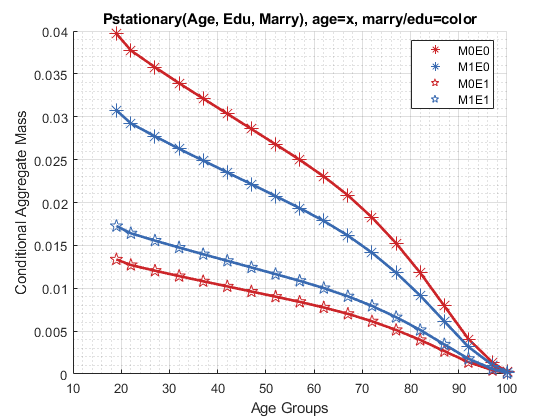

mp_support_graph('cl_st_graph_title') = {'Pstationary(Age, Edu, Marry), age=x, marry/edu=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
ar_row_grid = ["M0E0", "M1E0", "M0E1", "M1E1"];
mp_support_graph('cl_st_xtitle') = {'Age Groups'};
mp_support_graph('cl_scatter_shapes') = {'*', '*', 'p', 'p' };
mp_support_graph('cl_colors') = {'red', 'blue', 'red', 'blue'};
ff_graph_grid((tb_prob_aem{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

#### Kids and Marry By Age Mass

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
tb_prob_amarrykids = ff_summ_nd_array("P(Age, Kids, Marry))", Phi_true, true, ["sum"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(Age, Kids, Marry))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    sum_age_19    sum_age_22    sum_age_27    sum_age_32    sum_age_37    sum_age_42    sum_age_47    sum_age_52    sum_age_57    sum_age_62    sum_age_67    sum_age_72    sum_age_77    sum_age_82    sum_age_87    sum_age_92    sum_age_97    sum_age_100
    _____    ____    _____    __________    __________    __________    __________    __________    __________    __________    __

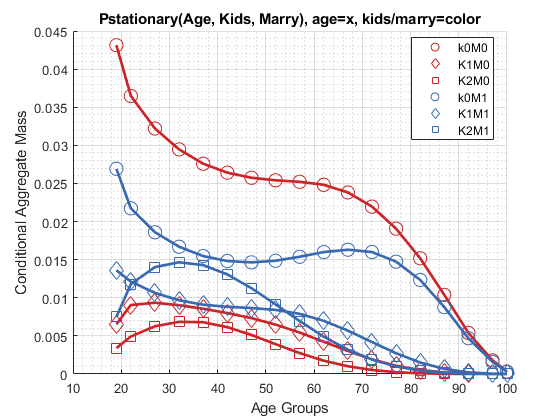

mp_support_graph('cl_st_graph_title') = {'Pstationary(Age, Kids, Marry), age=x, kids/marry=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
ar_row_grid = ["k0M0", "K1M0", "K2M0", "k0M1", "K1M1", "K2M1"];
mp_support_graph('cl_scatter_shapes') = { 'o', 'd' ,'s', 'o', 'd', 's'};
mp_support_graph('cl_colors') = {'red', 'red', 'red', 'blue', 'blue', 'blue'};
mp_support_graph('cl_st_xtitle') = {'Age Groups'};
ff_graph_grid((tb_prob_amarrykids{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Probability Mass Asset and Shock Dimensions

Where are the mass at?

% Get the Joint distribution over all states
Phi_true = mp_dsvfi_results('Phi_true');
Phi_true = Phi_true/sum(Phi_true(:));
% Define Graph Inputs
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = false; % do not log

#### Asset and Shock Mass

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [1,4,5,6,3,2];
% Value Function
tb_prob_az = ff_summ_nd_array("P(A,Z))", Phi_true, true, ["sum"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     sum_shock__0_91976    sum_shock__0_45988    sum_shock_0    sum_shock_0_45988    sum_shock_0_91976
    _____    ________    __________________    __________________    ___________    _________________    _________________

      1             0          0.046176               0.14732           0.16223          0.064321             0.010937    
      2      0.013744         0.0052226               0.02207            0.0317          0.027163            0.0018262    
      3       0.10995         0.0057555               0.03251           0.05058          0.029396            0.0074894    
      4       0.37109         0.0037705              0.028953          0.057641          0.038441       

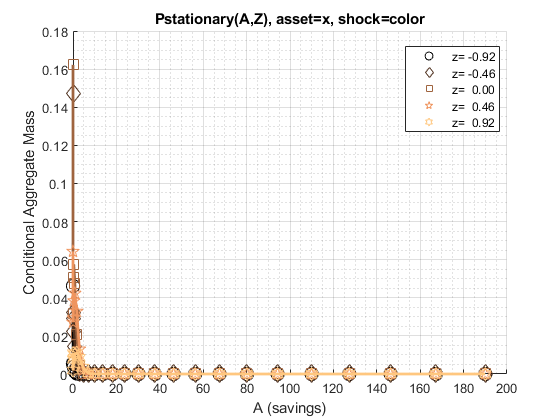

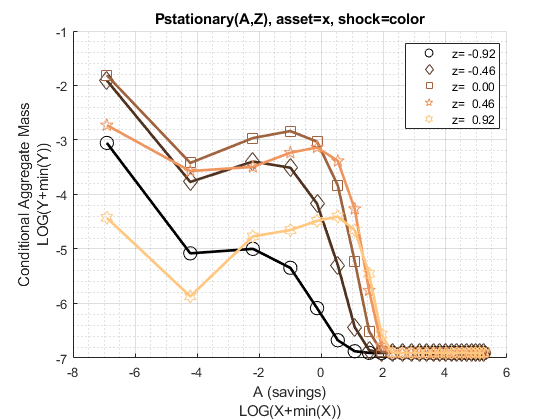

mp_support_graph('cl_st_graph_title') = {'Pstationary(A,Z), asset=x, shock=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
mp_support_graph('cl_st_xtitle') = {'A (savings)'};
mp_support_graph('st_rowvar_name') = 'z=';
mp_support_graph('it_legend_select') = 5; 
mp_support_graph('st_rounding') = '6.2f';
mp_support_graph('bl_graph_logy') = true;
mp_support_graph('cl_colors') = 'copper';
ff_graph_grid((tb_prob_az{1:end, 3:end})', eta_grid, agrid, mp_support_graph);% Consumption Choices

#### Asset Mass by Age

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [3,4,5,6,1,2];
% Value Function
tb_prob_aage = ff_summ_nd_array("P(A,Z))", Phi_true, true, ["sum"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     sum_age_19    sum_age_22    sum_age_27    sum_age_32    sum_age_37    sum_age_42    sum_age_47    sum_age_52    sum_age_57    sum_age_62    sum_age_67    sum_age_72    sum_age_77    sum_age_82    sum_age_87    sum_age_92    sum_age_97    sum_age_100
    _____    ________    __________    __________    __________    __________    __________    __________    __________    __________    __________    

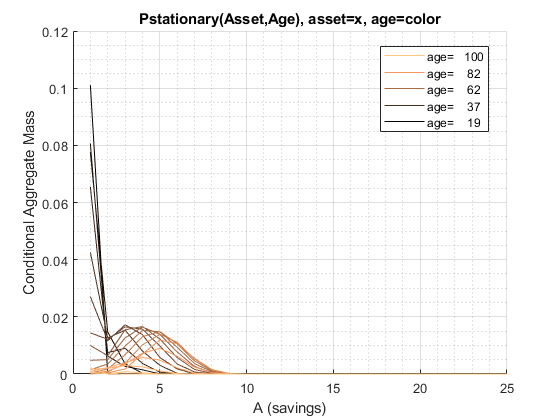

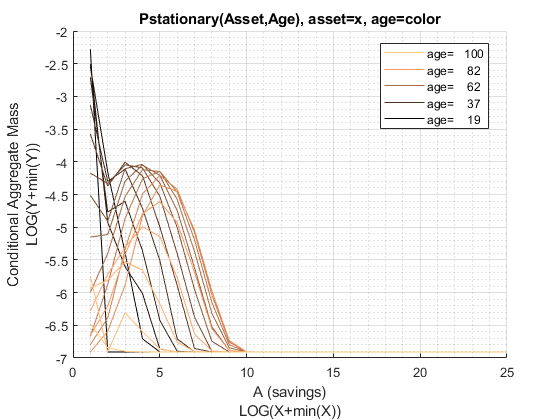

mp_support_graph('cl_st_graph_title') = {'Pstationary(Asset,Age), asset=x, age=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
mp_support_graph('cl_st_xtitle') = {'A (savings)'};
mp_support_graph('st_rowvar_name') = 'age=';
mp_support_graph('it_legend_select') = 5; 
mp_support_graph('st_rounding') = '6.0f';
mp_support_graph('bl_graph_logy') = true;
mp_support_graph('cl_colors') = 'copper';
ff_graph_grid((tb_prob_aage{1:end, 3:end})', age_grid, agrid, mp_support_graph);% Consumption Choices

## Probability Statistics A, C and V Conditional on Ages

Where are the mass at?

Phi_true = mp_dsvfi_results('Phi_true');
ap_ss = mp_dsvfi_results('ap_ss');
c_ss = mp_dsvfi_results('c_ss');
v_ss = mp_dsvfi_results('v_ss');
n_ss = mp_dsvfi_results('n_ss');
for it_ctr=1:size(ap_ss, 1)
    display(['age =' num2str(age_grid(it_ctr))]);
    % construct input data
    Phi_true_age = Phi_true(it_ctr, :, :, : ,: ,:);
    ap_ss_age = ap_ss(it_ctr, :, :, : ,: ,:);
    c_ss_age = c_ss(it_ctr, :, :, : ,: ,:);
    v_ss_age = v_ss(it_ctr, :, :, : ,: ,:);
    n_ss_age = n_ss(it_ctr, :, :, : ,: ,:);
    
    mp_cl_ar_xyz_of_s = containers.Map('KeyType','char', 'ValueType','any');
    mp_cl_ar_xyz_of_s('ap_ss') = {ap_ss_age(:), zeros(1)};
    mp_cl_ar_xyz_of_s('c_ss') = {c_ss_age(:), zeros(1)};
    mp_cl_ar_xyz_of_s('v_ss') = {v_ss_age(:), zeros(1)};
    mp_cl_ar_xyz_of_s('n_ss') = {n_ss_age(:), zeros(1)};
    mp_cl_ar_xyz_of_s('ar_st_y_name') = ["ap_ss", "c_ss", "v_ss", "n_ss"];
    
    % controls
    mp_support = containers.Map('KeyType','char', 'ValueType','any');
    mp_support('ar_fl_percentiles') = [0.01 10 25 50 75 90 99.99];
    mp_support('bl_display_final') = true;
    mp_support('bl_display_detail') = false;    
    mp_support('bl_display_drvm2outcomes') = false;  
    mp_support('bl_display_drvstats') = false;
    mp_support('bl_display_drvm2covcor') = false;

    % Call Function     
    mp_cl_mt_xyz_of_s = ff_simu_stats(Phi_true_age(:)/sum(Phi_true_age,'all'), mp_cl_ar_xyz_of_s, mp_support);
end

age =19


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss         c_ss        v_ss          n_ss   
    _____________________    __________    ________    _________    __________

      {'mean'        }        0.0070506     0.64718      -5.6393        1.8895
      {'sd'          }          0.02437     0.25992       4.1402       0.93753
      {'coefofvar'   }           3.4565     0.40162     -0.73418       0.49618
      {'min'         }                0     0.22955      -22.996             1
      {'max'         }           189.36      36.412       6.1144             4
      {'pYis0'       }          0.79974           0            0             0
      {'pYls0'       }                0           0      0.93274             0
      {'pYgr0'       }          0.20026           1      0.06726             1
      {'

age =22


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss        c_ss         v_ss         n_ss   
    _____________________    _________    _________    _________    _________

      {'mean'        }        0.010536      0.71863      -4.9135       2.0433
      {'sd'          }        0.047573      0.29743       3.9581       1.0228
      {'coefofvar'   }          4.5152      0.41389     -0.80557      0.50056
      {'min'         }               0      0.24627      -20.588            1
      {'max'         }          188.13       37.879       5.9417            4
      {'pYis0'       }         0.88542            0            0            0
      {'pYls0'       }               0            0      0.93742            0
      {'pYgr0'       }         0.11458            1     0.062584            1
      {'pYisMINY' 

age =27


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss        c_ss         v_ss         n_ss   
    _____________________    _________    _________    _________    _________

      {'mean'        }        0.035189      0.84594      -4.2425       2.1401
      {'sd'          }         0.10161       0.3471        3.712       1.0657
      {'coefofvar'   }          2.8877      0.41032     -0.87495      0.49795
      {'min'         }               0      0.28399       -18.38            1
      {'max'         }          187.08       39.451       5.7581            4
      {'pYis0'       }         0.73623            0            0            0
      {'pYls0'       }               0            0      0.90388            0
      {'pYgr0'       }         0.26377            1     0.096117            1
      {'pYisMINY' 

age =32


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss        c_ss         v_ss         n_ss   
    _____________________    _________    _________    _________    _________

      {'mean'        }         0.09682      0.93037      -3.8066       2.1893
      {'sd'          }         0.19493      0.37161       3.5096       1.0842
      {'coefofvar'   }          2.0133      0.39942     -0.92199       0.4952
      {'min'         }               0      0.31413      -16.885            1
      {'max'         }          185.95       41.278       5.5426            4
      {'pYis0'       }         0.51079            0            0            0
      {'pYls0'       }               0            0      0.89629            0
      {'pYgr0'       }         0.48921            1      0.10371            1
      {'pYisMINY' 

age =37


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss        c_ss         v_ss         n_ss   
    _____________________    _________    _________    _________    _________

      {'mean'        }         0.20005      0.98049      -3.5042       2.2064
      {'sd'          }         0.32552      0.38821       3.3565       1.0899
      {'coefofvar'   }          1.6272      0.39593     -0.95784      0.49397
      {'min'         }               0      0.33626      -15.847            1
      {'max'         }          184.47       43.458        5.297            4
      {'pYis0'       }         0.32463            0            0            0
      {'pYls0'       }               0            0      0.86576            0
      {'pYgr0'       }         0.67537            1      0.13424            1
      {'pYisMINY' 

age =42


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss        c_ss         v_ss         n_ss   
    _____________________    _________    _________    _________    _________

      {'mean'        }         0.33808       1.0121      -3.2752         2.19
      {'sd'          }         0.47333       0.4056       3.2429       1.0843
      {'coefofvar'   }          1.4001      0.40076     -0.99016      0.49514
      {'min'         }               0      0.35073      -15.147            1
      {'max'         }          182.56       46.074       5.0233            4
      {'pYis0'       }          0.1978            0            0            0
      {'pYls0'       }               0            0      0.84255            0
      {'pYgr0'       }          0.8022            1      0.15745            1
      {'pYisMINY' 

age =47


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss        c_ss         v_ss         n_ss  
    _____________________    _________    _________    _________    ________

      {'mean'        }         0.50078       1.0341      -3.0915      2.1449
      {'sd'          }         0.62271      0.43063       3.1498      1.0683
      {'coefofvar'   }          1.2435      0.41642      -1.0188     0.49805
      {'min'         }               0       0.3581      -14.702           1
      {'max'         }          180.03       49.261       4.7208           4
      {'pYis0'       }         0.14384            0            0           0
      {'pYls0'       }               0            0       0.8428           0
      {'pYgr0'       }         0.85616            1       0.1572           1
      {'pYisMINY'    }      

age =52


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss         c_ss         v_ss         n_ss  
    _____________________    __________    _________    _________    ________

      {'mean'        }          0.67905       1.0499       -2.939      2.0761
      {'sd'          }          0.76152      0.45786       3.0579      1.0408
      {'coefofvar'   }           1.1215      0.43609      -1.0405     0.50131
      {'min'         }                0      0.35879      -14.446           1
      {'max'         }            176.8       53.265       4.3856           4
      {'pYis0'       }         0.054072            0            0           0
      {'pYls0'       }                0            0      0.82111           0
      {'pYgr0'       }          0.94593            1      0.17889           1
      {'pYisMINY' 

age =57


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss        c_ss         v_ss         n_ss   
    _____________________    _________    _________    _________    _________

      {'mean'        }          0.8685       1.0562      -2.8145       1.9893
      {'sd'          }         0.87996      0.48408       2.9529       1.0001
      {'coefofvar'   }          1.0132      0.45833      -1.0492      0.50275
      {'min'         }               0      0.34595      -14.328            1
      {'max'         }          172.57       56.104       4.0138            4
      {'pYis0'       }        0.018081            0            0            0
      {'pYls0'       }               0            0      0.84545            0
      {'pYgr0'       }         0.98192            1      0.15455            1
      {'pYisMINY' 

age =62


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss        c_ss         v_ss         n_ss   
    _____________________    _________    _________    _________    _________

      {'mean'        }          1.0645       1.0519      -2.7208       1.8923
      {'sd'          }         0.97581      0.50382       2.8274      0.94543
      {'coefofvar'   }         0.91669      0.47897      -1.0392      0.49961
      {'min'         }               0      0.32634      -14.346            1
      {'max'         }          167.23        56.78        3.616            4
      {'pYis0'       }       0.0045999            0            0            0
      {'pYls0'       }               0            0      0.83494            0
      {'pYgr0'       }          0.9954            1      0.16506            1
      {'pYisMINY' 

age =67


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss         c_ss          v_ss         n_ss   
    _____________________    _________    __________    __________    _________

      {'mean'        }           1.261        1.0341       -2.6679       1.7984
      {'sd'          }          1.0513       0.51415        2.6848      0.88126
      {'coefofvar'   }         0.83374       0.49719       -1.0063      0.49002
      {'min'         }               0       0.30614        -14.46            1
      {'max'         }           167.2        64.448         3.202            4
      {'pYis0'       }       0.0024946             0             0            0
      {'pYls0'       }               0             0       0.82496            0
      {'pYgr0'       }         0.99751             1       0.17504            

age =72


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss          c_ss          v_ss         n_ss  
    _____________________    __________    __________    __________    ________

      {'mean'        }           1.4503       0.99895       -2.6703      1.7105
      {'sd'          }           1.1102       0.51478        2.5421     0.80784
      {'coefofvar'   }          0.76548       0.51532      -0.95198     0.47229
      {'min'         }         0.013744       0.27812       -14.677           1
      {'max'         }           157.84        75.535        2.7857           4
      {'pYis0'       }                0             0             0           0
      {'pYls0'       }                0             0         0.873           0
      {'pYgr0'       }                1             1         0.127           

age =77


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss         c_ss          v_ss         n_ss  
    _____________________    _________    __________    __________    ________

      {'mean'        }          1.0298       0.90837       -2.7374      1.6355
      {'sd'          }         0.85191       0.50667        2.4174     0.73183
      {'coefofvar'   }         0.82723       0.55778       -0.8831     0.44746
      {'min'         }               0       0.21429       -16.289           1
      {'max'         }          146.35        79.778        2.3734           4
      {'pYis0'       }       0.0095952             0             0           0
      {'pYls0'       }               0             0       0.89544           0
      {'pYgr0'       }          0.9904             1       0.10456           1
      {'

age =82


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss        c_ss          v_ss         n_ss  
    _____________________    _________    _________    __________    ________

      {'mean'        }         0.57058       0.8755       -2.8128      1.5775
      {'sd'          }         0.57711      0.52335        2.3454     0.66134
      {'coefofvar'   }          1.0114      0.59777      -0.83381     0.41924
      {'min'         }               0      0.21429       -13.784           1
      {'max'         }          130.37       93.612        1.9724           4
      {'pYis0'       }        0.043352            0             0           0
      {'pYls0'       }               0            0       0.92777           0
      {'pYgr0'       }         0.95665            1      0.072225           1
      {'pYisMINY' 

age =87


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss        c_ss         v_ss         n_ss   
    _____________________    _________    ________    __________    _________

      {'mean'        }         0.24452      0.6636        -3.124       1.5366
      {'sd'          }         0.33271     0.38735        2.1702      0.60333
      {'coefofvar'   }          1.3607      0.5837       -0.6947      0.39263
      {'min'         }               0     0.21429       -11.509            1
      {'max'         }          111.12      110.94        1.6137            4
      {'pYis0'       }         0.15684           0             0            0
      {'pYls0'       }               0           0        0.9366            0
      {'pYgr0'       }         0.84316           1      0.063402            1
      {'pYisMINY' 

age =92


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss        c_ss         v_ss         n_ss   
    _____________________    _________    ________    __________    _________

      {'mean'        }        0.079119     0.44633       -3.5132       1.5104
      {'sd'          }         0.15182     0.24831        1.7962      0.56122
      {'coefofvar'   }          1.9189     0.55633      -0.51126      0.37157
      {'min'         }               0     0.21429       -9.7314            1
      {'max'         }          94.272      140.46        1.3379            4
      {'pYis0'       }         0.63896           0             0            0
      {'pYls0'       }               0           0       0.99261            0
      {'pYgr0'       }         0.36104           1     0.0073871            1
      {'pYisMINY' 

age =97


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss         c_ss          v_ss          n_ss   
    _____________________    __________    _________    __________    __________

      {'mean'        }        0.0034473      0.32741       -3.8917        1.4953
      {'sd'          }         0.017598      0.17268        1.4313       0.53482
      {'coefofvar'   }           5.1047      0.52743      -0.36778       0.35766
      {'min'         }                0      0.21429       -8.5399             1
      {'max'         }           58.433        164.6         1.155             4
      {'pYis0'       }          0.87876            0             0             0
      {'pYls0'       }                0            0       0.99957             0
      {'pYgr0'       }          0.12124            1    0.00042933   

age =100


xxx tb_outcomes: all stats xxx
    OriginalVariableNames    ap_ss      c_ss          v_ss          n_ss   
    _____________________    _____    _________    __________    __________

      {'mean'        }          0       0.24152       -3.9944        1.4869
      {'sd'          }          0      0.034062       0.76481       0.51938
      {'coefofvar'   }        NaN       0.14103      -0.19147       0.34931
      {'min'         }          0       0.21429       -7.4764             1
      {'max'         }          0        220.89       0.99547             4
      {'pYis0'       }          1             0             0             0
      {'pYls0'       }          0             0             1             0
      {'pYgr0'       }          0             1    1.1907e-08             1
      {'pYisMINY'    }          1     